This document reformulates strain properly, as a % of deformation ( $\frac{\Delta l}{l_0}$) rather than just $\Delta l$, as was in `planar_arm2`.

syms rho Pi
syms k l_0 l epsilon % Universal muscle parameters
syms g_0 g_0_b g_0_t % Poses
syms k_a l_0_a l_a epsilon_a % Left muscle parameters
syms k_b l_0_b l_b epsilon_b % Right muscle parameters

assume([rho k l_0 l epsilon k_b l_0_b l_b epsilon_b k_a l_0_a l_a epsilon_a], "real")

syms k_epsilon k_k
assume([k_epsilon k_k], "real")

% Parameter initialization
g_0_a = SE2(-rho, 0, pi/2); % Pose of the base of muscle A in world frame
g_0_b = SE2(0, 0, pi/2); % Pose of base of muscle B in world frame
g_b_ba = inv(g_0_b) * g_0_a; % Frame transformation from B to A in frame of muscle base

theta_b_ba = atan2(g_b_ba(2, 1), g_b_ba(1, 1));
t_b_ba = g_b_ba(1:2, 3);
ad_b_ba = ad_se2(theta_b_ba, t_b_ba);

struct_vals = struct();
struct_vals.Pi = pi;

struct_vals.rho = 0.03; % meters
struct_vals.k_k = 0.1; % Newtons/meter
struct_vals.k_epsilon = 1000000000; % Newtons/meter
struct_vals.l_0_a = 0.1; % meters
struct_vals.l_0_b = 0.08; % meters

struct_syms_a = struct();
struct_syms_a.k = k_a;
struct_syms_a.l_0 = l_0_a;
struct_syms_a.l = l_a;
struct_syms_a.epsilon = epsilon_a;

struct_syms_b = struct();
struct_syms_b.k = k_b;
struct_syms_b.l_0 = l_0_b;
struct_syms_b.l = l_b;
struct_syms_b.epsilon = epsilon_b;

mat_K = diag([k_epsilon, 10, k_k]);
v_a = [epsilon; 0; k];
h = [1; 0; epsilon*k] + v_a;
h_tilde = l_0 * h;


% Construt quadratic objective function
U = v_a' * mat_K * v_a;
U_all = subs(U, struct_syms_a) + subs(U, struct_syms_b)

$$U\_all = k_{\epsilon }\,{\epsilon_{a}}^{2}+k_{\epsilon }\,{\epsilon_{b}}^{2}+k_{k}\,{k_{a}}^{2}+k_{k}\,{k_{b}}^{2}$$


% Construct lie-algebraic constraint
h_tilde_hat = se2(h_tilde(1), h_tilde(3), h_tilde(3));
mat_constraints = g_b_ba*subs(h_tilde_hat, struct_syms_a) - subs(h_tilde_hat, struct_syms_b)*g_b_ba

$$mat\_constraints = \left(\begin{array}{ccc} 0 & l_{0,b}\,\left(k_{b}+\epsilon_{b}\,k_{b}\right)-l_{0,a}\,\left(k_{a}+\epsilon_{a}\,k_{a}\right) & l_{0,a}\,\left(\epsilon_{a}+1\right)-l_{0,b}\,\left(\epsilon_{b}+1\right)+l_{0,b}\,\rho \,\left(k_{b}+\epsilon_{b}\,k_{b}\right)\\ l_{0,a}\,\left(k_{a}+\epsilon_{a}\,k_{a}\right)-l_{0,b}\,\left(k_{b}+\epsilon_{b}\,k_{b}\right) & 0 & l_{0,a}\,\left(k_{a}+\epsilon_{a}\,k_{a}\right)-l_{0,b}\,\left(k_{b}+\epsilon_{b}\,k_{b}\right)\\ 0 & 0 & 0 \end{array}\right)$$

v_constraints = [mat_constraints(1, 2); mat_constraints(1, 3)];

struct_vals.l_0_a = 0.12;
struct_vals.l_0_b = 0.13;
struct_vals.k_k = 0.0000000001; % Newton meters
struct_vals.k_epsilon = 1000000; % Newton / meter
f_generate_func = @(sym_func) matlabFunction(subs(sym_func, struct_vals));

f_U = f_generate_func(U_all);
f_constraint = f_generate_func(v_constraints(1:2));

% x: epsilon_b, epsilon_t, k_b, k_t
f_obj = @(x) f_U(x(1), x(2), x(3), x(4));
f_nonlcon = @(x) smart_deal([], f_constraint(x(1), x(2), x(3), x(4)));
x_0 = [0, 0, 0, 0];

opt_fmincon = optimoptions('fmincon', "algorithm", "interior-point");

v_soln = fmincon(f_obj, x_0, [], [], [], [], [], [], f_nonlcon, opt_fmincon);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


struct_soln = struct();
struct_soln.epsilon_a = v_soln(1);
struct_soln.epsilon_b = v_soln(2);
struct_soln.k_a = v_soln(3);
struct_soln.k_b = v_soln(4);

print_results(struct_soln)

Muscle A strain:
   5.9980e-12

Muscle A curvature:
    2.7778

Muscle B strain:
  -5.9987e-12

Muscle B curvature:
    2.5641



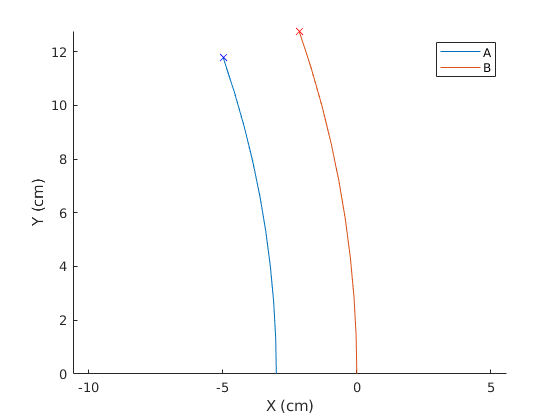

plot_results(struct_soln, struct_vals, g_0_a=g_0_a, g_0_b=g_0_b);

eqn = ad_b_ba * l_0_a * [1; 0; k_a] == l_0_b * [1; 0; k_b]

$$eqn = \left(\begin{array}{c} l_{0,a}+k_{a}\,l_{0,a}\,\rho =l_{0,b}\\ 0=0\\ k_{a}\,l_{0,a}=k_{b}\,l_{0,b} \end{array}\right)$$

soln_analytic = solve(eqn, [k_a, k_b])

soln_analytic = struct with fields:
    k_a: [1×1 sym]
    k_b: [1×1 sym]


k_analytic = subs(soln_analytic, struct_vals)

k_analytic = struct with fields:
    k_a: [1×1 sym]
    k_b: [1×1 sym]


struct_soln_analytic = struct();
struct_soln_analytic.k_a = eval(k_analytic.k_a);
struct_soln_analytic.k_b = eval(k_analytic.k_b);
struct_soln_analytic.epsilon_a = 0;
struct_soln_analytic.epsilon_b = 0;
plot_results(struct_soln_analytic, struct_vals, g_0_a=g_0_a, g_0_b=g_0_b);

mat_A = ad_b_ba * l_0_a * [0 0 1; 0 0 0; 1 0 0] - l_0_b * [0 0 1; 0 0 0; 0 1 0];
eval(null(subs(mat_A, struct_vals)))

ans =     2.7778
    2.5641
    1.0000


mat_K_2 = diag([1e4 1e4 k_k]);
null(subs(2*(l_0_a/l_0_b)^2 * ad_b_ba'*mat_K_2*ad_b_ba + mat_K_2, struct_vals)) 

 
ans =
 
Empty sym: 3-by-0
 


test_mat = eval(subs(l_0_b / l_0_a * pinv([0 0 1; 0 0 0; 1 0 0]) * inv(ad_b_ba), struct_vals));
test_h_tilde_b = struct_vals.l_0_b * [1; 0; 0.5]

test_h_tilde_b =     0.1300
         0
    0.0650


test_h_tilde_a = test_mat * test_h_tilde_b

test_h_tilde_a =     0.0704
         0
    0.1387


test_h_a = test_h_tilde_a / struct_vals.l_0_a

test_h_a =     0.5868
         0
    1.1560


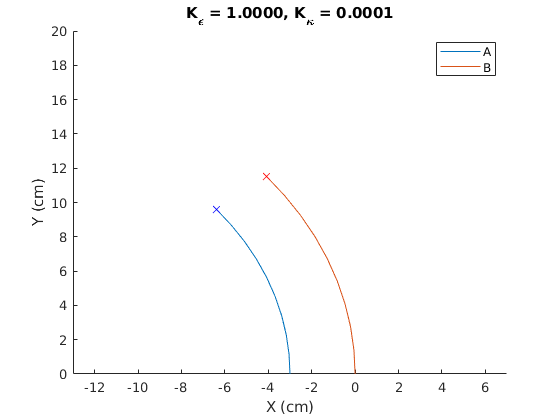

l_0_a_min = 0.05; % Meters
l_0_a_max = 0.15; % Meters
t = linspace(0, 2*pi, 50);
l_0_vals = zeros(2, length(t));
l_0_vals(1, :) = (l_0_a_max - l_0_a_min) * 0.5 * sin(t) + (l_0_a_max + l_0_a_min) * 0.5; % l_0_a
l_0_vals(2, :) = 0.13 * ones(size(l_0_vals(1, :))); % l_0_b

struct_vals.l_0_a = l_0_vals(1, 1);
struct_vals.l_0_b = l_0_vals(2, 1);

struct_vals.k_k = 0.0001; % Newton meters
struct_vals.k_epsilon = 1; % Newton / meter

fig = figure();
hold on;
default_struct = struct();
default_struct.epsilon_a = 0;
default_struct.k_a = 0;
default_struct.epsilon_b = 0;
default_struct.k_b = 0;

[g_a, g_b] = plot_results(default_struct, struct_vals, g_0_a=g_0_a, g_0_b=g_0_b, plot=false);
l_ga = plot(g_a(1, :), g_a(2, :));
l_gb = plot(g_b(1, :), g_b(2, :));
l_ga_end = plot(g_a(1, end), g_a(2, end), 'bx');
l_gb_end = plot(g_b(1, end), g_b(2, end), 'rx');

title(sprintf("K_\\epsilon = %.4f, K_\\kappa = %.4f", struct_vals.k_epsilon, struct_vals.k_k))
legend("A", "B")
xlabel("X (cm)")
ylabel("Y (cm)")
ylim([0, 20]);
xlim([-10, 10] - struct_vals.rho * 100);

for i = 1 : size(l_0_vals, 2)
    
    struct_vals.l_0_a = l_0_vals(1, i);
    struct_vals.l_0_b = l_0_vals(2, i);
    f_generate_func = @(sym_func) matlabFunction(subs(sym_func, struct_vals));
    
    f_U = f_generate_func(U_all);
    f_constraint = f_generate_func(v_constraints(1:2));
    
    % x: epsilon_b, epsilon_t, k_b, k_t
    f_obj = @(x) f_U(x(1), x(2), x(3), x(4));
    f_nonlcon = @(x) smart_deal([], f_constraint(x(1), x(2), x(3), x(4)));
    x_0 = [0, 0, 0, 0];
    
    opt_fmincon = optimoptions('fmincon', "algorithm", "interior-point", "display", "off");
    
    v_soln = fmincon(f_obj, x_0, [], [], [], [], [], [], f_nonlcon, opt_fmincon);
    struct_soln = struct();
    struct_soln.epsilon_a = v_soln(1);
    struct_soln.epsilon_b = v_soln(2);
    struct_soln.k_a = v_soln(3);
    struct_soln.k_b = v_soln(4);
    
    [g_a, g_b] = plot_results(struct_soln, struct_vals, g_0_a=g_0_a, g_0_b=g_0_b, plot=false);
    
    l_ga.XData = g_a(1, :);
    l_ga.YData = g_a(2, :);
    
    l_gb.XData = g_b(1, :);
    l_gb.YData = g_b(2, :);
    
    l_ga_end.XData = g_a(1, end);
    l_ga_end.YData = g_a(2, end);
    
    l_gb_end.XData = g_b(1, end);
    l_gb_end.YData = g_b(2, end);
    
    drawnow
    frame = getframe(fig);
    if i == 1
        pos = get(fig, 'Position');
        width = pos(3);
        height = pos(4);

        % Preallocate data (for storing frame data)
        mov = zeros(height, width, 1, length(l_0_vals), 'uint8');
        [mov(:,:,1,i), map] = rgb2ind(frame.cdata, 256, 'nodither');
    else
        mov(:,:,1,i) = rgb2ind(frame.cdata, map, 'nodither');
    end
end

imwrite(mov, map, sprintf("media/%s.gif", datestr(now)), 'DelayTime', 0, 'LoopCount', inf)

% Constraint validation
f_hat = @(v_se2) se2(v_se2(1), v_se2(2), v_se2(3));
% Calculate the theoretical h_b via the adjoint
h_b_adj = eval(chain_subs(g_b_ba * f_hat(h_tilde) * inv(g_b_ba), {struct_syms_a, struct_soln, struct_vals}))

h_b_adj =          0   -0.6803    0.1244
    0.6803         0         0
         0         0         0


% Calculate difference between adjoint-predicted vs fmincon solution h_b
h_diff = h_b_adj - eval(chain_subs(f_hat(h_tilde), {struct_syms_b, struct_soln, struct_vals}))

h_diff = 	1.0e+-8 *

         0    0.1011   -0.0017
   -0.1011         0         0
         0         0         0


function g_out = calc_posn(g_0, l_0, epsilon, k, options)
% Calculate (and interpolate) positions given an initial pose, a default length,
% and a curvature.
% - g_0: Initial pose (SE2 matrix)
% - l_0: Neutral (unstrained) length
% - epsilon: Strain
% - options: use options.t to determine the timestamp. Defaults to 1.
    arguments
        g_0
        l_0
        epsilon
        k
        options.t (1, :) double = 1;
    end

    l = l_0* (1 + epsilon);
    
    g_out = zeros(3, length(options.t));
    
    for i = 1 : length(options.t)
        SE2_pose_i = g_0 * expm_se2(l*options.t(i), 0, l*k*options.t(i));
        g_out(:, i) = [SE2_pose_i(1, 3); SE2_pose_i(2, 3); atan2(SE2_pose_i(2, 1), SE2_pose_i(1, 1))];
    end
end

function print_results(soln, options)
    arguments
        soln
        options.U = nan;
        options.struct_vals = nan;
    end
    for i = 1
        disp("Muscle A strain:");
        disp(soln.epsilon_a)
        
        disp("Muscle A curvature:");
        disp(soln.k_a)
        
        disp("Muscle B strain:");
        disp(soln.epsilon_b)
        
        disp("Muscle B curvature:");
        disp(soln.k_b)
    end
    
    if ~isnan(options.U) && isfield(options.struct_vals, "k_k")
        disp("Energy:")
        disp(eval(subs(subs(options.U, options.struct_vals), soln)));
    end
end

function [g_a, g_b] = plot_results(soln, struct_vals, options)
    arguments
        soln
        struct_vals
        options.g_0_a = SE2(-struct_vals.rho, 0, pi/2);
        options.g_0_b = SE2(0, 0, pi/2);
        options.plot = true;
    end
    options.g_0_a = subs(options.g_0_a, struct_vals);
    options.g_0_b = subs(options.g_0_b, struct_vals);
    
    n = 10;
    g_b = calc_posn(options.g_0_b, struct_vals.l_0_b, soln.epsilon_b, soln.k_b, t=linspace(0, 1, n));
    g_a = calc_posn(options.g_0_a, struct_vals.l_0_a, soln.epsilon_a, soln.k_a, t=linspace(0, 1, n));
    
    g_b = g_b * 100;
    g_a = g_a * 100;
    
    if options.plot
        figure()
        hold on;
        plot(g_a(1, :), g_a(2, :))
        plot(g_b(1, :), g_b(2, :))
        plot(g_a(1, end), g_a(2, end), 'bx');
        plot(g_b(1, end), g_b(2, end), 'rx');
        
        legend("A", "B")
        xlabel("X (cm)")
        ylabel("Y (cm)")
        axis equal
    end
end